**Linear Support Vector Machine with slack variables.**

Apply the linear SVM with slack variables (set ε = 0.2 and C = 10) to the training data.

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

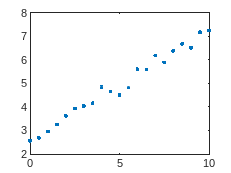

data = [ 0    2.5584
        0.5000    2.6882
        1.0000    2.9627
        1.5000    3.2608
        2.0000    3.6235
        2.5000    3.9376
        3.0000    4.0383
        3.5000    4.1570
        4.0000    4.8498
        4.5000    4.6561
        5.0000    4.5119
        5.5000    4.8346
        6.0000    5.6039
        6.5000    5.5890
        7.0000    6.1914
        7.5000    5.8966
        8.0000    6.3866
        8.5000    6.6909
        9.0000    6.5224
        9.5000    7.1803
       10.0000    7.2537];

x = data(:, 1);
y = data(:, 2);
l = length(x);

% Plot Data
plot(x,y,".");

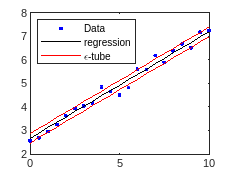

%% linear regression - primal problem with slack variables
C = 10;
epsilon = 0.2;

% define the problem
Q = [ 1              zeros(1,2*l+1)
      zeros(2*l+1,1) zeros(2*l+1) ];
  
c = [ 0 ; 0 ; C*ones(2*l,1)]; 

D = [-x -ones(l,1) -eye(l)   zeros(l)
      x  ones(l,1)  zeros(l) -eye(l)];
  
d = epsilon*ones(2*l,1) + [-y;y];

options = optimset('Display','off');
% solve the problem
solution = quadprog(Q,c,D,d,[],[],[-inf;-inf;zeros(2*l,1)],[],[],options);

% compute w
w = solution(1);

% compute b
b = solution(2);

% compute slack variables xi+ and xi-
xip = solution(3:2+l);
xim = solution(3+l:2+2*l);

% find regression and epsilon-tube
z = w.*x + b ;
zp = w.*x + b + epsilon ;
zm = w.*x + b - epsilon ;

%% plot the solution

plot(x,y,'b.',x,z,'k-',x,zp,'r-',x,zm,'r-');
legend('Data','regression',...
    '\epsilon-tube','Location','NorthWest')